%% HW5 #2
global y0  %need to pass y0 from script to functions

format compact 
format short
data =readmatrix('HW5_2_data.xlsx');
%initial conditions
y0=[0.05 0];

beta0(1) = 2;
beta0(2) = 3;
beta0(3) = 3;
beta0(4) = 3;
beta0(5) = 14;

%% create xobs and stdev for each dependent variable

stdX = 0.9;
stdP = 0.9;
stdS = 1.0;

xobs=data(:,1);
xobs(1,2)=stdX; xobs(1,3)=stdP; xobs(1,4)=stdS; %stdev for each y variable in separate columns, to feed into nlinfit

%% yobs for plotting
yobsX=data(:,2);
yobsP=data(:,3);
yobsS=data(:,4);

%% yobs for nlinfit using weighted least squares
yobsX2=data(:,2)/stdX;
yobsP2=data(:,3)/stdP;
yobsS2=data(:,4)/stdS;
yobs=[yobsX2; yobsP2; yobsS2]; %yobs normalized using weighted least squares


%% Scaled sensitivity coefficients before running inverse problem
%to determine a) which parameters can be estimated, and b) which parameters
%wil be most accurate (lowest relative error)
xs=min(xobs):0.01:max(xobs); %xs are the times for SSCs to make a smooth curve.
%make xs a column.
xs=xs';
ns=length(xs);%length of xs for plotting
fnameFOR=@SeborgFOR; %function name can be as you wish
Xp=SSC_V3(beta0,xs,fnameFOR);
p=length(beta0);

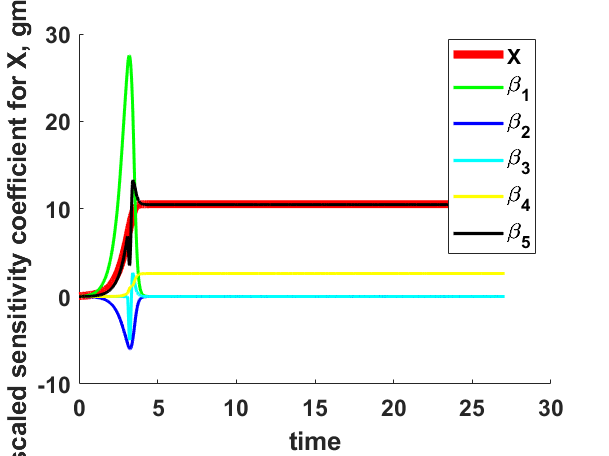

%% plot X' for each dependent variable
%plot for X
cmap = ['r' 'g' 'b' 'c' 'y'  'k' 'm' ]';
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
%plot predicted y to see the total span
ypred=fnameFOR(beta0,xs);
h1(1)=plot(xs,ypred(1:ns),'-','color',cmap(1,:),'LineWidth',5); %plot the predicted X to compare to SSCs
for i=1:p
    h1(i+1) = plot(xs,Xp(1:ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend(h1,'X','\beta_1','\beta_2','\beta_3','\beta_4','\beta_5','location','best')
xlabel('time'); ylabel('scaled sensitivity coefficient for X, gmol/L');

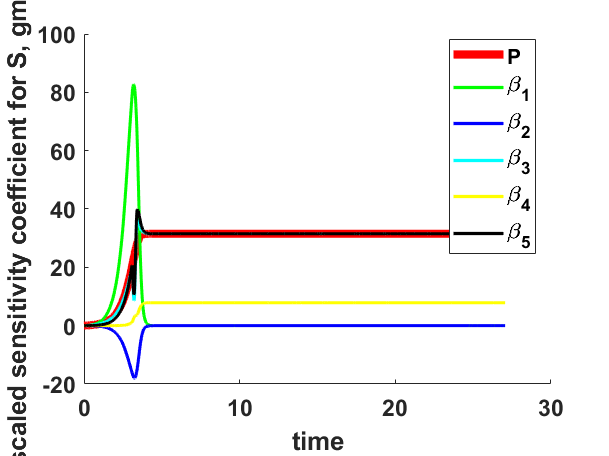


%% SSC plot for P
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
ypred=fnameFOR(beta0,xs);
h2(1)=plot(xs,ypred(ns+1:2*ns),'-','color',cmap(1,:),'LineWidth',5); %plot the predicted P to compare to SSCs
for i=1:p
    h2(i+1) = plot(xs,Xp(ns+1:2*ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend(h2,'P','\beta_1','\beta_2','\beta_3','\beta_4','\beta_5','location','best')
xlabel('time'); ylabel('scaled sensitivity coefficient for S, gmol/L');

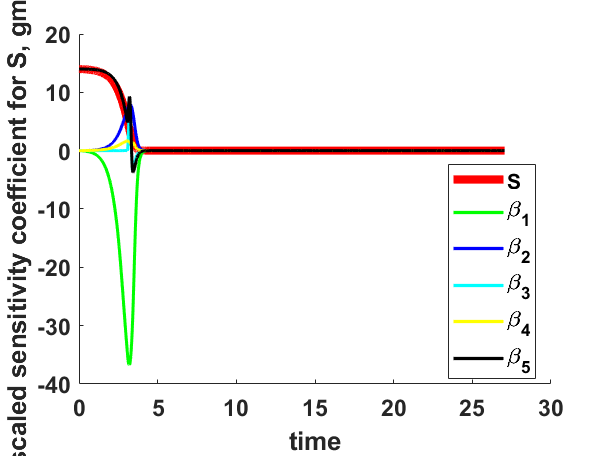


%% SSC plot for S
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
ypred=fnameFOR(beta0,xs);
h3(1)=plot(xs,ypred(2*ns+1:3*ns),'-','color',cmap(1,:),'LineWidth',5); %plot the predicted C to compare to SSCs
for i=1:p
    h3(i+1) = plot(xs,Xp(2*ns+1:3*ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend('S','\beta_1','\beta_2','\beta_3','\beta_4','\beta_5','location','best')
xlabel('time'); ylabel('scaled sensitivity coefficient for S, gmol/L');

%% Estimate parameters using inverse problem with nlinfit
fnameINV=@SeborgINV;
[beta,resids,J,COVB,mse] = nlinfit(xobs, yobs,fnameINV, beta0);
rmse=sqrt(mse) %mean square error = SS/(n-p)

rmse = 0.4374

n=length(xobs(:,1));      	
beta=beta'

beta =     0.2227
    3.6813
    0.2614
    0.3022
   14.9914


p=length(beta);
%% Each parameter estimate is reported:
mumax=beta(1)

mumax = 0.2227

Ks=beta(2)

Ks = 3.6813

YPX=beta(3)

YPX = 0.2614

YXS=beta(4)

YXS = 0.3022

S0=beta(5)

S0 = 14.9914


%% save residuals for each dependent variable
residsX=resids(1:n);
residsP=resids(n+1:2*n);
residsS=resids(2*n+1:3*n);

%% R is the correlation matrix for the parameters, sigma is the standard error vector
[R,sigma]=corrcov(COVB);
R

R =     1.0000    0.9853   -0.0834    0.3397    0.2600
    0.9853    1.0000   -0.0432    0.1970    0.2985
   -0.0834   -0.0432    1.0000   -0.2378    0.0285
    0.3397    0.1970   -0.2378    1.0000   -0.3261
    0.2600    0.2985    0.0285   -0.3261    1.0000


sigma

sigma =     0.0268
    1.7376
    0.0833
    0.0344
    0.2068



condX = cond(J)

condX = 828.2168

%find row and column of max correlation
maxcorr=0;
for i=1:p
    for j=1:p
        if abs(R(i,j))>maxcorr && abs(R(i,j))~=1
       maxcorr=abs(R(i,j)); %replace old maxcorr with new maxcorr
       maxrow=i; %row of max correlation coeff
       maxcol=j; %column of max corr coeff
   end
    end
end

maxcorr

maxcorr = 0.9853

maxcorrlocation = strcat(num2str(maxrow),num2str(maxcol)) %concatenate the two location numbers into one string

maxcorrlocation = '12'



relerr=sigma./beta

relerr =     0.1202
    0.4720
    0.3187
    0.1137
    0.0138



%relative error in percent for each parameter
relerr1=100*relerr(1) %percent error beta1

relerr1 = 12.0235

relerr2=100*relerr(2) %percent error beta2

relerr2 = 47.1999

relerr3=100*relerr(3) %percent error beta3

relerr3 = 31.8704

relerr4=100*relerr(4) %percent error beta4

relerr4 = 11.3747

relerr5=100*relerr(5) %percent error beta5

relerr5 = 1.3794


%condition number, detXTX
conditionNumber = cond(J); 
detXTX = det(J'*J); 


%% confidence intervals for parameters


%% computed ypredicted by solving ode45 once with the estimated parameters
ypred=SeborgFOR(beta,xs);
ypredX=ypred(1:ns);
ypredP=ypred(ns+1:2*ns);
ypredS=ypred(2*ns+1:3*ns);

%Biomass, X, at 21 minutes
t21=find(xs==21)

t21 = 2101

X21=ypredX(t21)

X21 = 1.8684

%Product, P, at 21 minutes
P21=ypredP(t21)

P21 = 0.4754

%Substrate, S, at 21 minutes
S21=ypredS(t21)

S21 = 7.1552


yspan=max(ypred)-min(ypred);
relrmse=rmse/yspan

relrmse = 0.0292

%mean of the residuals
meanr=mean(relrmse)

meanr = 0.0292

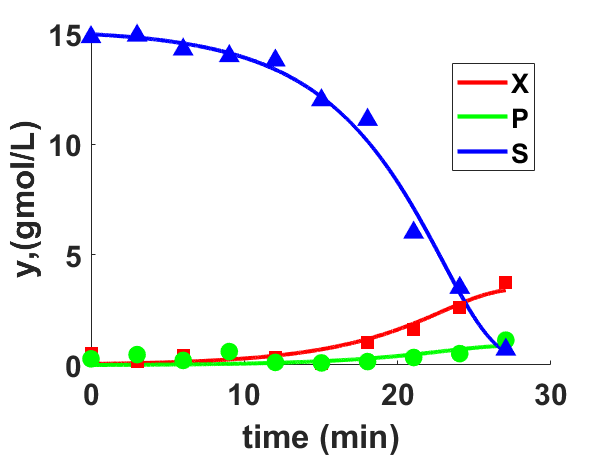

%% plot all ypred and data
figure 
hold on
h4(1)=plot(xs, ypredX, '-r','linewidth',2.5);
h4(2)=plot(xs, ypredP, '-g','linewidth',2.5);
h4(3)=plot(xs, ypredS,'-b','linewidth',2.5); %predicted y values
xp=xobs(:,1);%create one vector of x values for plotting
plot(xp, yobsX, 'rs', 'markerfacecolor','r','markersize',10);
plot(xp, yobsP, 'go', 'markerfacecolor','g','markersize',10);
plot(xp, yobsS, 'b^','markerfacecolor','b','markersize',10);
legend(h4,'X','P','S','location','best')
xlabel('time (min)')
ylabel('y,(gmol/L)')
set(gca, 'fontsize',18,'fontweight','bold');

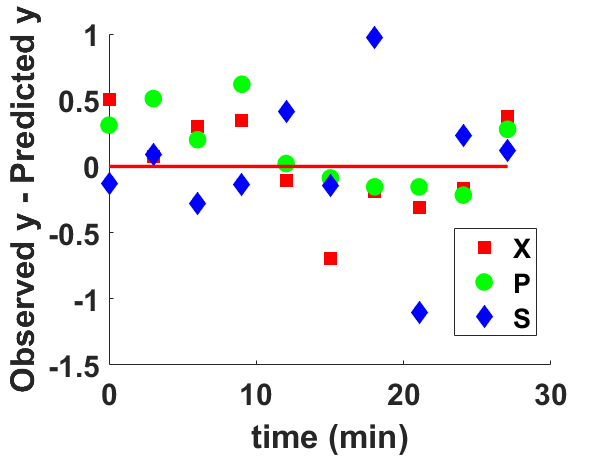


%% residual scatter plot
figure
hold on
h5(1)=plot(xp, residsX, 'rs','Markerfacecolor', 'r', 'markersize',10);
h5(2)=plot(xp, residsP, 'go','Markerfacecolor', 'g', 'markersize',10);
h5(3)=plot(xp, residsS, 'bd','Markerfacecolor', 'b', 'markersize',10);
YLine = [0 0]; 
XLine = [0 max(xp)];
plot (XLine, YLine,'R','linewidth',2); %plot a straight red line at zero
ylabel('Observed y - Predicted y')
xlabel('time (min)')
set(gca, 'fontsize',18,'fontweight','bold');
legend(h5,'X','P','S','location','best')

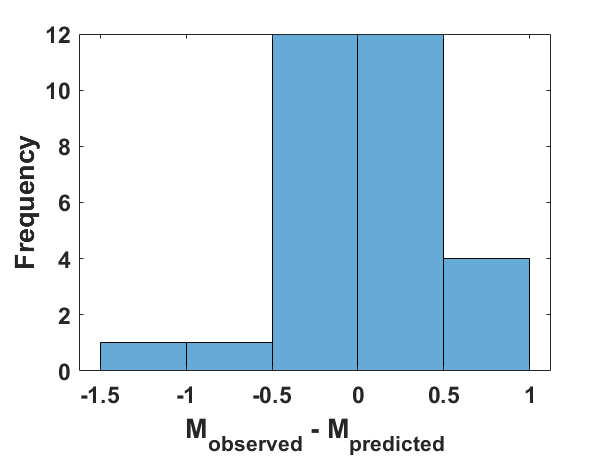


%% residuals histogram
figure
histogram(resids);
set(gca, 'fontsize',14,'fontweight','bold');
xlabel('M_{observed} - M_{predicted}','fontsize',16,'fontweight','bold')
ylabel('Frequency','fontsize',16,'fontweight','bold')

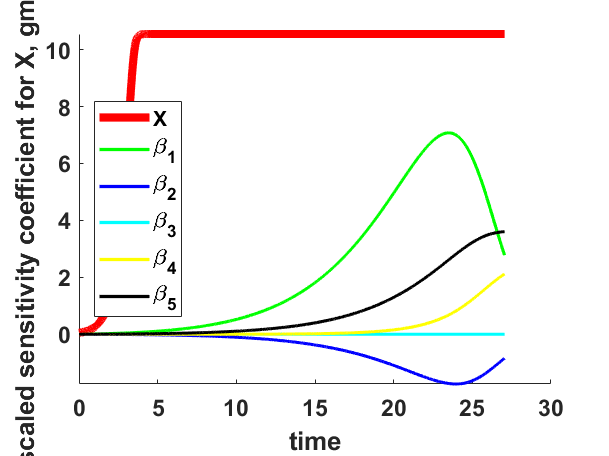

%% Scaled sensitivity coefficients after running inverse problem
%to determine a) which parameters can be estimated, and b) which parameters
%wil be most accurate (lowest relative error)
%  repeat the code above for SSC, but use 'beta' instead of 'beta0'
Xp=SSC_V3(beta,xs,fnameFOR);

%plot for X
cmap = ['r' 'g' 'b' 'c' 'y'  'k' 'm' ]';
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
%plot predicted y to see the total span
ypred=fnameFOR(beta0,xs);
h1(1)=plot(xs,ypred(1:ns),'-','color',cmap(1,:),'LineWidth',5); %plot the predicted X to compare to SSCs
for i=1:p
    h1(i+1) = plot(xs,Xp(1:ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend(h1,'X','\beta_1','\beta_2','\beta_3','\beta_4','\beta_5','location','best')
xlabel('time'); ylabel('scaled sensitivity coefficient for X, gmol/L');


SSCX121=Xp(t21,1) %SSC for beta1 at time = 21 min

SSCX121 = 5.7749

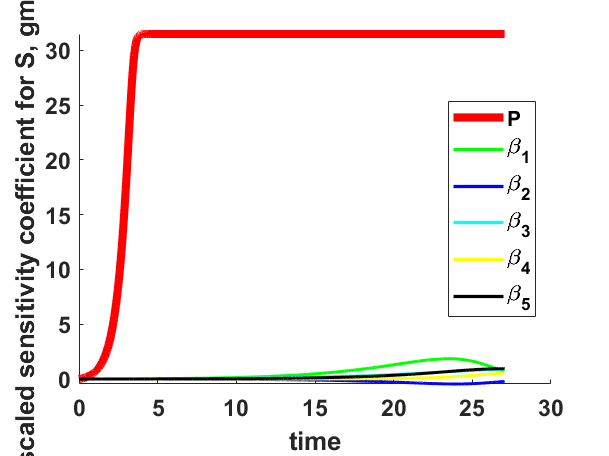


%% SSC plot for P
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
ypred=fnameFOR(beta0,xs);
h2(1)=plot(xs,ypred(ns+1:2*ns),'-','color',cmap(1,:),'LineWidth',5); %plot the predicted P to compare to SSCs
for i=1:p
    h2(i+1) = plot(xs,Xp(ns+1:2*ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend(h2,'P','\beta_1','\beta_2','\beta_3','\beta_4','\beta_5','location','best')
xlabel('time'); ylabel('scaled sensitivity coefficient for S, gmol/L');

SSCP321= Xp(ns+t21,3)%SSC for beta3 at time = 21 min

SSCP321 = 0.4754

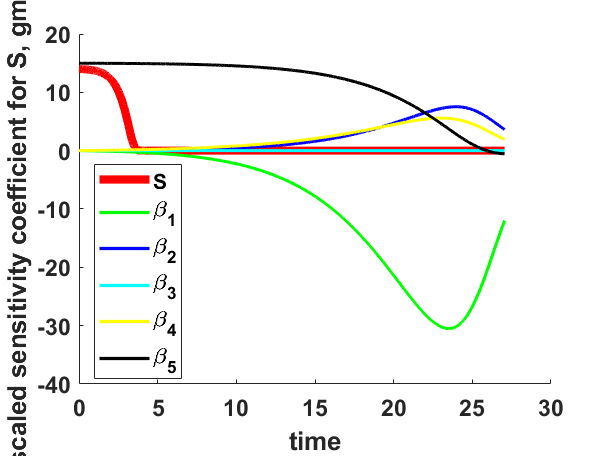


%% SSC plot for S
figure
hold on
set(gca, 'fontsize',14,'fontweight','bold');
ypred=fnameFOR(beta0,xs);
h3(1)=plot(xs,ypred(2*ns+1:3*ns),'-','color',cmap(1,:),'LineWidth',5); %plot the predicted C to compare to SSCs
for i=1:p
    h3(i+1) = plot(xs,Xp(2*ns+1:3*ns,i),'-','color',cmap(i+1,:),'LineWidth',2);
end
legend('S','\beta_1','\beta_2','\beta_3','\beta_4','\beta_5','location','best')
xlabel('time'); ylabel('scaled sensitivity coefficient for S, gmol/L');

SSCS521=Xp(2*ns+t21,5)

SSCS521 = 8.0519

%% functions

function y = SeborgFOR(beta,t)
global y0
tspan=t; 
[t,y]=ode45( @ff, tspan, [y0, beta(5)]   );

    function dy = ff(t,y) %function that computes the dydt
        mu=  beta(1) * ( y(3) ./ (beta(2) + y(3)) )      ; %specific growth rate
        dy(1)= mu * y(1)     ; %biomass
        dy(2)= beta(3) * mu * y(1)     ; %product
        dy(3)= -(1/beta(4)) * mu*y(1) - mu*y(1)     ; %substrate
        dy=dy';
    end
y1=y(:,1);y2=y(:,2);y3=y(:,3);
y=[y1;y2;y3];
end

function y = SeborgINV(beta,t)
% %Seborg 2.17 using different stdev for each of the 3 dep variables
global y0
tspan=t(:,1); %we want y at every t
stdX=t(1,2); stdP=t(1,3); stdS=t(1,4);
[t,y]=ode45( @ff, tspan, [y0, beta(5)]  );

    function dy = ff(t,y) %function that computes the dydt
        mu=   beta(1) * ( y(3) ./ (beta(2) + y(3)) )      ; %specific growth rate
        dy(1)=  mu * y(1) ; %biomass
        dy(2)=  beta(3) * mu * y(1) ; %product
        dy(3)=  -(1/beta(4)) * mu*y(1) - mu*y(1)  ; %substrate
        dy=dy';
    end

%divide by the stdev
y1=y(:,1)/stdX; 
y2=y(:,2)/stdP; 
y3=y(:,3)/stdS;
y = [y1;y2;y3] ;
end

function Xp=SSC_V3(beta,x,yfunc)
%Computes scaled sensitivity coefficients =Xp, nxp matrix
%can have k dependent variables that are stacked in a column vector
%all y1s, then all y2s, ...last are yks
%n is the number of data
%p is the number of parameters
%Xp1 = dY/dbeta1~[y(beta1(1+d), beta2,...betap) - y(beta1,
%beta2,...betap)]/d...
%d is the arbitrary delta, usually 0.001
%beta is the p x 1 parameter vector
%yhat is nx1 vector, the y values when only one parameter has been successively perturbed by d
%ypred is nx1 vector,  the y values when parameters are set to beta
%betain is px1 vector, the parameter values with only one parameter perturbed by d
%x are the independent variables (can be one or more independent variables)
%yfunc is a function (m file or an anonymous) defined by the user outside
%of this file

%% X' = scaled sensitivity coefficients using forward-difference
% This is a forward problem with known approximate parameters
d=0.001;
ypred=yfunc(beta,x);
for i = 1:length(beta)  %scaled sens coeff for forward problem
    betain = beta; %reset beta
    betain(i) = beta(i)*(1+d);
    yhat{i} = yfunc(betain,x);
    SSC{i} = (yhat{i}-ypred)/d;%scaled sens coeff for ith parameter
    Xp(:,i)=SSC{i}; %extract from cell array to 2D array
end
end